% (实验8)f分布与标准正态分布的近似程度实验
% 为例便于观察，标准正态分布只取方差为1，而其期望可变，以调整其位置观察与f分布曲线的关系
% 好像没什么
clf;
mu = 0.8

mu = 0.8000

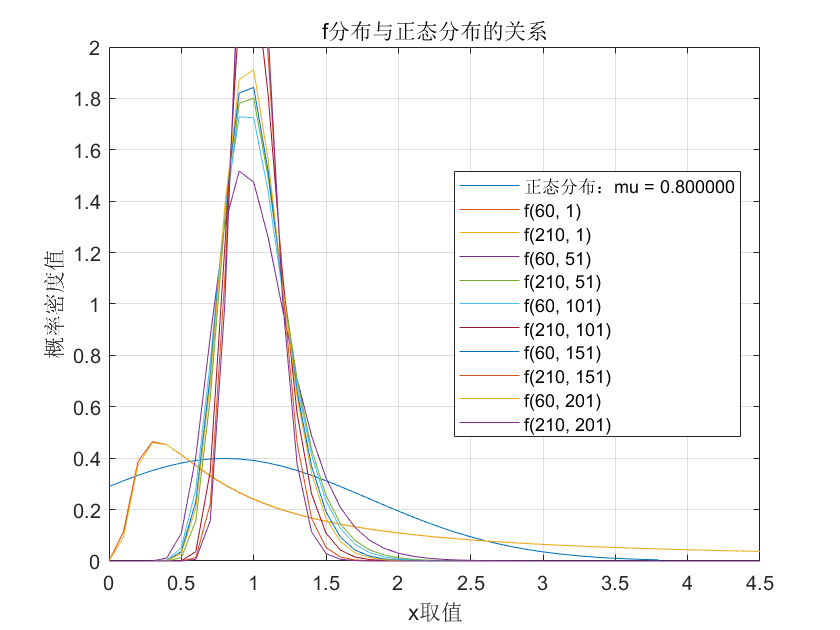

xs = (mu - 3):0.1:(mu + 3);
norm_y = normpdf(xs, mu, 1);

n1_ys = zeros(5, 46);
n2_ys = zeros(5, 46);
str_mat = strings(11);
str_mat(1) = sprintf("正态分布：mu = %f", mu);
cnt = 1;
x = 0:0.1:4.5;
for n2 = 1:50:210
    n1_ys(cnt, :) = fpdf(x, 60, n2);
    n2_ys(cnt, :) = fpdf(x, 210, n2);
    str_mat(2 * cnt) = sprintf("f(%d, %d)", 60, n2);
    str_mat(2 * cnt + 1) = sprintf("f(%d, %d)", 210, n2);
    cnt = cnt + 1;
end

plot(xs, norm_y);
hold on; axis on; grid on;
for i = 1:5
    plot(x, n1_ys(i, :));
    plot(x, n2_ys(i, :));
end
legend(str_mat(1:11), "Location",'best');
xlim([0, 4.5]);
ylim([0, 2]);
xlabel("x取值");
ylabel("概率密度值");
title("f分布与正态分布的关系");